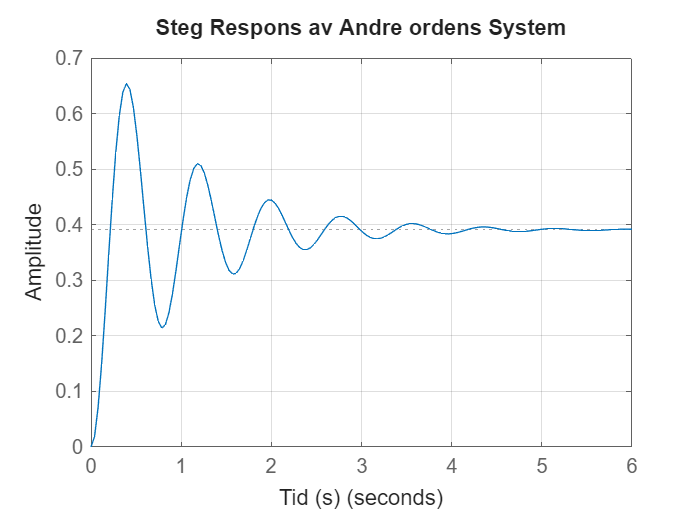

% Andreordens systemanalyse i MATLAB

% Parametere for systemet
K = 0.391;        % Gain
w = 8;            % Omega, udempet naturlig frekvens (rad/s)
c = 0.125;        % Zeta, dempningsforhold

% Andre ordens overføringsfunksjon
numerator = K * w^2;                     % Tellerpolynomet
denominator = [1, 2*c*w, w^2];           % Nevnerpolynomet
G = tf(numerator, denominator);          % Overføringsfunksjon

% Beregn karakteristiske tider og egenskaper
info = stepinfo(G);                      % Beregn systemegenskaper
overshoot = info.Overshoot;              % Oversving i prosent
riseTime = info.RiseTime;                % Stigningstid
peakTime = info.PeakTime;                % Toppunktstid
settlingTime = info.SettlingTime;        % Innsvingingstid

% Beregninger av dempet naturlig frekvens
w_d = w * sqrt(1 - c^2);                 % Dempet naturlig frekvens (rad/s)

% Symbolsk representasjon
syms s t
G_sym = K * (w^2) / (s^2 + 2*c*w*s + w^2); % Symbolsk overføringsfunksjon
M_sym = 1 / s;                            % Steginngang
Y_sym = G_sym * M_sym;                    % Systemutgang i Laplace
y_time = ilaplace(Y_sym);                 % Stegrespons i tidsdomenet

% Plot stegrespons
figure;
step(G);
title('Steg Respons av Andre ordens System');
xlabel('Tid (s)');
ylabel('Amplitude');
grid on;


% Utskrift av resultater
fprintf('Systemegenskaper:\n');

Systemegenskaper:


fprintf('Gain (K): %.3f\n', K);

Gain (K): 0.391


fprintf('Naturlig frekvens (w): %.3f rad/s\n', w);

Naturlig frekvens (w): 8.000 rad/s


fprintf('Dempningsforhold (c): %.3f\n', c);

Dempningsforhold (c): 0.125


fprintf('Dempet naturlig frekvens (w_d): %.3f rad/s\n', w_d);

Dempet naturlig frekvens (w_d): 7.937 rad/s


fprintf('Stigningstid (Tr): %.3f sekunder\n', riseTime);

Stigningstid (Tr): 0.144 sekunder


fprintf('Toppunktstid (Tp): %.3f sekunder\n', peakTime);

Toppunktstid (Tp): 0.393 sekunder


fprintf('Innsvingingstid (Ts): %.3f sekunder\n', settlingTime);

Innsvingingstid (Ts): 3.663 sekunder


fprintf('Oversving (OS): %.3f%%\n', overshoot);

Oversving (OS): 67.293%


fprintf('\nOverføringsfunksjon Y(s):\n');


Overføringsfunksjon Y(s):


disp(vpa(Y_sym, 3)); % Skriver ut Y(s)

$$\frac{25.0}{s\,\left(s^{2}+2.0\,s+64.0\right)}$$

fprintf('\nSteg respons i tidsdomenet, y(t):\n');


Steg respons i tidsdomenet, y(t):


disp(vpa(y_time, 3)); % Skriver ut y(t)

$$0.391-0.391\,{\mathrm{e}}^{-1.0\,t}\,\left(\cos\left(7.94\,t\right)+0.126\,\sin\left(7.94\,t\right)\right)$$